# Example of reaching a desired payload position.

% Problem is broken down into a few steps:
% 1. Error dynamics calculated: rotational and translational
% 2. IF angular error is minimal, proceed with STEP 4.
% 3. OTHERWISE:
%   a. Determine payload PURE rotational input to minimize angle error 
%   b. Determine robot's required input to cause (a)
% 4. IF translation error is minimal, proceed with STEP 6.
% 5. OTHERWISE:
%   a. Determine payload PURE translation input to minimize distance error
%   b. Determine robot's required input to cause (a)
% 6. Repeat from STEP 2. if necessary
% 7. Done!


% Problem description

% Initial payload position: 
p_p0 = [0; 2; 0];
% Goal payload position: 
p_pg = [5; 12; 0];


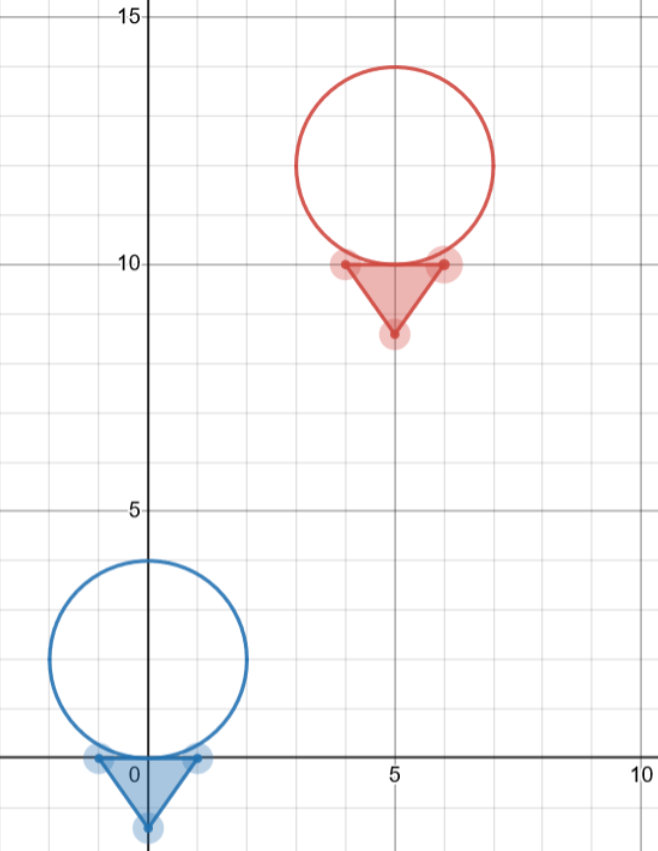

## Calculate error and return *payload* control input

syms e_dot_psi K_p K_d e_dot u_p_psi G_bar u_p

G = p_pg - p_p0;
L = [0; 1; 0];

% Angle error between G (goal vec) and L (LoA)
eqn1 = u_p_psi == K_p * e_psi + K_d * e_dot_psi;

e_psi = -acos(dot(G, L) / (norm(G)*norm(L)));

sol = solve(eqn1, u_p_psi);
U_p_rot = subs(sol, {K_p, K_d}, {1, 0}) * [0;0;1]

$$U\_p\_rot = \left(\begin{array}{c} 0\\ 0\\ -\frac{522020799781813}{1125899906842624} \end{array}\right)$$


% Position error: G (goal vec)
eqn2 = u_p == K_p * e + K_d * e_dot;

e = G_bar;

sol = solve(eqn2, u_p);
U_p_trans = subs(sol, {K_p, K_d, G_bar}, {1, 0, G})

$$U\_p\_trans = \left(\begin{array}{c} 5\\ 10\\ 0 \end{array}\right)$$



% Get total error
U_p = eval(U_p_rot + U_p_trans)

U_p =     5.0000
   10.0000
   -0.4636


## Calculate robot's control input to achieve above payload motion

syms a_r_x a_r_y a_p_x a_p_y m_p m_r mu g v_hat_x v_hat_y 

% Calculate a_r (ignoring rotational component)
a_r = [a_r_x; a_r_y];
a_p = [a_p_x; a_p_y];
v_hat = [v_hat_x; v_hat_y];

eqn3 = a_r == m_p/m_r * (a_p + mu*g*v_hat);
sol = solve(eqn3, a_r);
sol = subs(sol, {m_p, m_r, g, mu, v_hat_x, v_hat_y, a_p_x, a_p_y}, ...
                {1, 1, 9.81, 0.01, 0, 0, U_p(1), U_p(2)});

A_r = eval([sol.a_r_x; sol.a_r_y; 0])

A_r =      5
    10
     0



fprintf(['Thus in order to achieve u_p=[%.2f %.2f %.2f] TRANSLATION, \n' ...
        'we need to move robot a_r=[%.2f %.2f %.2f]'], U_p, A_r);

Thus in order to achieve u_p=[5.00 10.00 -0.46] TRANSLATION, 
we need to move robot a_r=[5.00 10.00 0.00]



% Calculate a_r (only rotational component)
syms I_p omega sigma a_r_perp
eqnRot = a_r_perp == I_p/m_r * omega_dot_p + m_p/m_r * mu * g * sigma * sign(omega);
sol = solve(eqnRot, a_r_perp);
sol = subs(sol, {m_p, m_r, g, mu, I_p, omega, sigma, omega_dot_p}, ...
            {1, 1, 9.81, 0.01, 2, 0, 2, U_p(3)});

A_r_perp = eval(sol);

fprintf('Thus the perpendicular component of a_r MUST be %.3f', A_r_perp)

Thus the perpendicular component of a_r MUST be -0.927


% To find a_r from a_r_perp, we must rotate initial tangent vector by theta_p ...
% and multiply by magnitude of a_r_perp:
syms theta_p
A_r_calculated = A_r_perp * [cos(theta_p); sin(theta_p)];
A_r_calculated = [eval(subs(A_r_calculated, theta_p, 0)); 0]

A_r_calculated =    -0.9273
         0
         0



fprintf('HOWEVER, to ROTATE alpha_p=%.2f, \n a_r must = [%.2f %.2f %.2f]', U_p(3), A_r_calculated)

HOWEVER, to ROTATE alpha_p=-0.46, 
 a_r must = [-0.93 0.00 0.00]

## Testing *forward* case to see payload's ACTUAL dynamics using calculated A_r

syms omega_dot_p chi
% omega_dot_app = 1/I_p * m_p * norm(a_r) * sin(chi);
omega_dot_app = 1/I_p * m_p * cross([0; -2; 0], A_r)' * [0;0;1]

$$omega\_dot\_app = -\frac{522020799781813\,m_{p}}{281474976710656\,I_{p}}$$

omega_dot_fric = 1/I_p * m_p * sigma * sign(omega);
eqnFwd = [a_p; omega_dot_p] == m_r/m_p * [a_r; omega_dot_app] - mu*g*[v_hat; omega_dot_fric];
sol = solve(eqnFwd, [a_p; omega_dot_p]);

A_r_old = A_r;
A_r = A_r_calculated;

CHI = atan2(norm(cross(A_r, L)), dot(A_r, L)); % acos(dot(A_r, L) / (norm(A_r)*norm(L)));
A_p = subs(sol, {m_p, m_r, g, mu, v_hat_x, v_hat_y, I_p, chi, omega, sigma, a_r_x, a_r_y}, ...
    {1, 1, 9.81, 0.01, 0, 0, 2, CHI, 0, 2, A_r(1), A_r(2)});

A_p = eval([A_p.a_p_x; A_p.a_p_y; A_p.omega_dot_p])

A_p =    -0.9273
         0
   -0.9273


% Calculate required motor values:
syms f_1 f_2 f_3 theta_1 theta_2 theta_3 R epsilon omega_dot_r

f_w = [f_1; f_2; f_3];

C_matrix = [-sin(theta_1) -sin(theta_2) -sin(theta_3);
     cos(theta_1) cos(theta_2) cos(theta_3);
     R/epsilon R/epsilon R/epsilon];

    % Substitute physical robot traits (simplify coupling matrix)
C = subs(C_matrix, [theta_1, theta_2, theta_3, R, epsilon], ...
         [pi/6, 5*pi/6, 9*pi/6, 0.07, 0.5]);

eqn6 = f_w == C \ [a_r; omega_dot_r]; % same as inv(C) * ...
sol = solve(eqn6, f_w);
F = subs(sol, [a_r_x, a_r_y, omega_dot_r], [A_r(1), A_r(2), 1]);

F = eval([F.f_1; F.f_2; F.f_3])

F =     6.4878
   -5.0592
    5.7143
